# Histogram-Based Divergence Estimation

This script introduces basic histogram methods for calculating divergences of continuous and discrete probability distributions.

## Initialize Workspace

% Clear everything:
clear all; close all force; clc;

% Path maintenance:
restoredefaultpath
addpath('matlab_tools')
addpath('project_tools')

% Initialize plotting sequence and grab plotting colors:
fignum = 0;
colors = grab_plot_colors;

## Step 1: Create a Synthetic Mixture Density

% These exercises use synthetic data to explore relationships between:
%     (i) the generating probability mass function (PMF),
%    (ii) sample size,
%   (iii) accuracy of resulting entropy estimators.
%
% We will use mixture densities with different kernels to generate
% semi-random distributions.

% How many kernels?
nKernels = 1;

% Which type(s) of kernel to use?
kernelType = 'Normal';

% Choose copula strength (only used in the case of a bivariate normal):
copulaCorrelation = 0.8;

% Create joint densities:
nMarginals = 2;
jointDensity = create_joint_density(nKernels,kernelType,nMarginals,copulaCorrelation);

% Screen report:
fprintf('Creating mixture densities with a copula correlation of %.2f ...',copulaCorrelation);

Creating mixture densities with a copula correlation of 0.80 ...

## Step 1.1: Plot the Synthetic Mixture Density

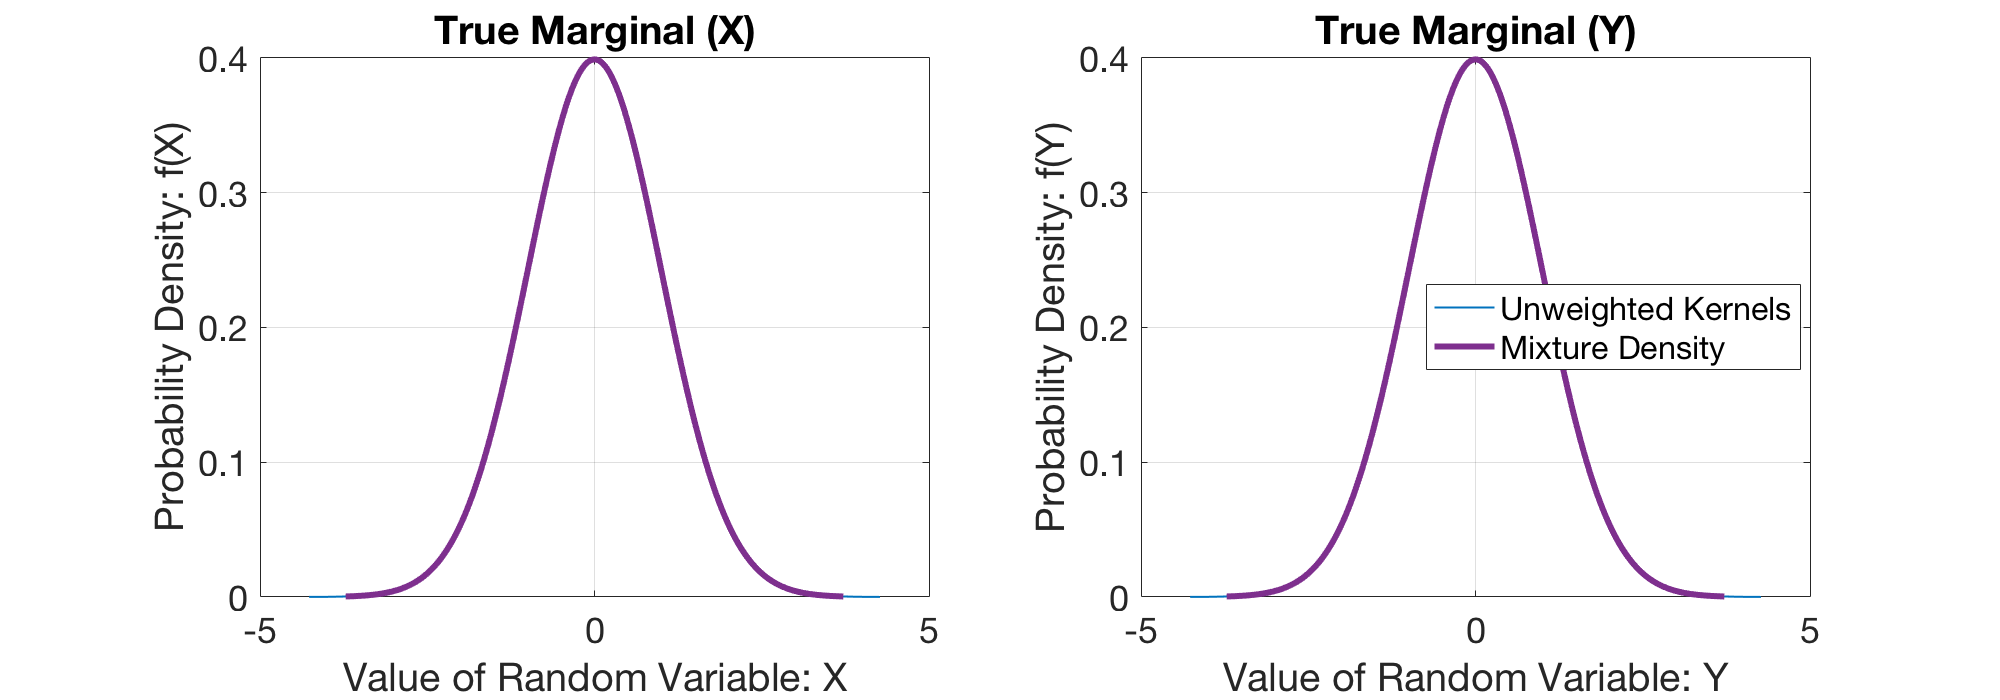

% Initialize a figure for plotting the mixture density:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
set(gcf,'position',[1,1,1000,350])

% Plot the first mixture:
subplot(1,2,1)
for k = 1:nKernels % plot each kernel
    [Xkernel,Ykernel] = plot_kernel_density(jointDensity.marginal{1},k);
    kfig = plot(Xkernel,Ykernel,'color',colors(1,:),'linewidth',1);
    hold on;
end

% Plot theoretical mixture density:
[Xtheoretical,Ytheoretical] = plot_mixture_density(jointDensity.marginal{1});
mfig = plot(Xtheoretical,Ytheoretical,'color',colors(4,:),'linewidth',3);

% labels & legend
ylabel('Probability Density: f(X)','fontsize',18);
xlabel('Value of Random Variable: X','fontsize',18);
title('True Marginal (X)','fontsize',24)

% plotting aesthetics
set(gca,'fontsize',18);
grid on;

% Plot the first mixture:
subplot(1,2,2)
for k = 1:nKernels % plot each kernel
    [Xkernel,Ykernel] = plot_kernel_density(jointDensity.marginal{2},k);
    kfig = plot(Xkernel,Ykernel,'color',colors(1,:),'linewidth',1);
    hold on;
end

% Plot theoretical mixture density:
[Xtheoretical,Ytheoretical] = plot_mixture_density(jointDensity.marginal{2});
mfig = plot(Xtheoretical,Ytheoretical,'color',colors(4,:),'linewidth',3);

% labels & legend
legend([kfig,mfig],'Unweighted Kernels','Mixture Density','location','best');
ylabel('Probability Density: f(Y)','fontsize',18);
xlabel('Value of Random Variable: Y','fontsize',18);
title('True Marginal (Y)','fontsize',24)

% plotting aesthetics
set(gca,'fontsize',18);
grid on;

## Step 2: Sample and Plot

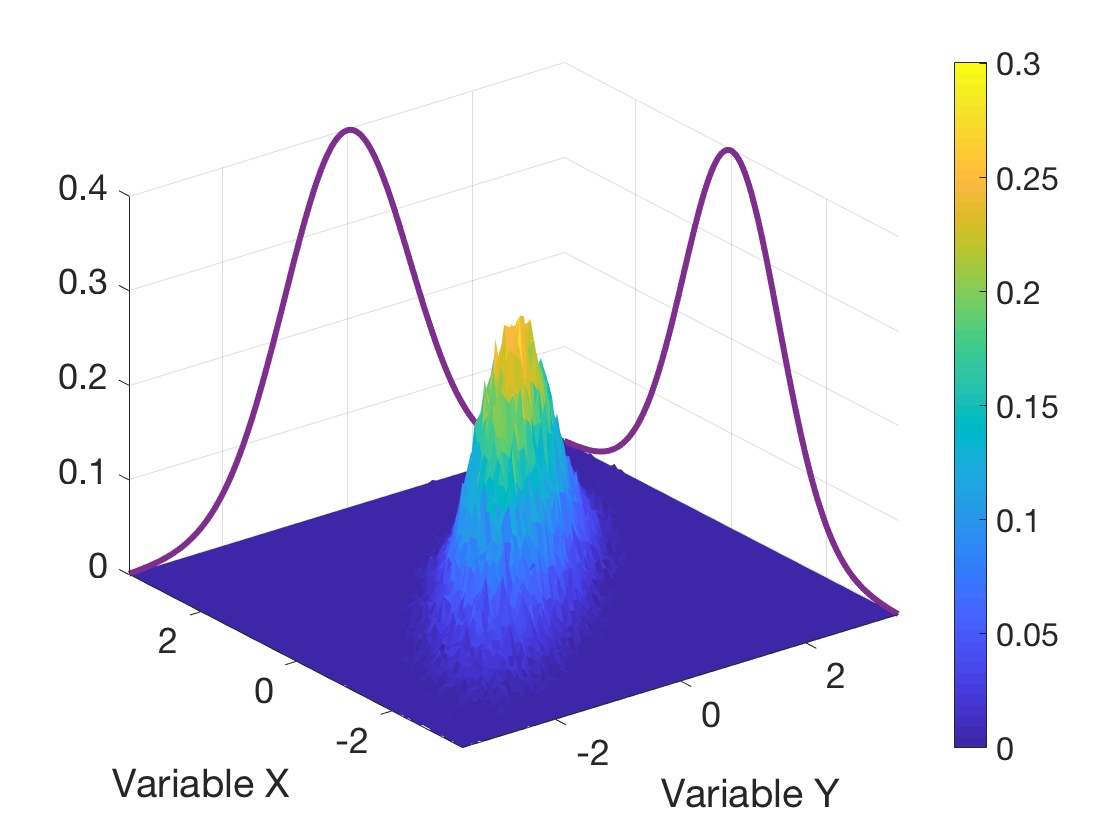

% How many samples?
logSamples = 5;
nSamples = round(10^logSamples);

% How many histogram bins?
nBins = 100;

% Sample the mixture density:
sample = sample_joint_density(jointDensity,nSamples);

% Discretize the sample:
[histCounts,histEdges] = hist2(sample,nBins);    % this is a custom function
binWidth(1) = histEdges(2,1) - histEdges(1,1);   % bin width in first dimension
binWidth(2) = histEdges(2,2) - histEdges(1,2);   % bin width in second dimension
histProbs = histCounts / nSamples;               % histogram counts -> probability mass
histDensities = histProbs / binWidth(1) / binWidth(2);  % probability mass -> probability density

% Initialize a figure for plotting the sample histogram:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);

% Plot sample histogram:
histCenters = zeros(nBins,2)./0;
histCenters(:,1) = histEdges(2:end,1) - 1/2*binWidth(1);
histCenters(:,2) = histEdges(2:end,2) - 1/2*binWidth(2);
sfig = surf(histCenters(:,2),histCenters(:,1),histDensities,'edgecolor','none');
hold on;

% Plot theoretical mixture densities:
[Xtheoretical,Ytheoretical] = plot_mixture_density(jointDensity.marginal{1});
mfig1 = plot3(zeros(size(Xtheoretical))+histCenters(end,2),...
    Xtheoretical,Ytheoretical,...
    'color',colors(4,:),'linewidth',3);

[Xtheoretical,Ytheoretical] = plot_mixture_density(jointDensity.marginal{2});
mfig2 = plot3(Xtheoretical,...
    zeros(size(Xtheoretical))+histCenters(end,1),...
    Ytheoretical,...
    'color',colors(4,:),'linewidth',3);

% Labels:
xlabel('Variable Y')
ylabel('Variable X')
axis([histCenters(1,2),histCenters(end,2),histCenters(1,1),histCenters(end,1)])
% legend([sfig,mfig1],'Sample Histogram','Marginals')

% Plot aesthetics:
set(gca,'fontsize',18);
grid on;
colorbar;

## Step 3: Estimate Entropy

% Calculate entropy analytically: h = -integral{p(X=x)) * ln[p(X=x)], dx}
% Only do this if there is a single Gaussian kernel in each marginal:
hTrue = 0/0;
if nKernels == 1 && strcmpi(kernelType,'Normal')
    
    % pull parameters from the joint distribution
    sgX = jointDensity.marginal{1}.params{1}(2)^2;
    sgY = jointDensity.marginal{2}.params{1}(2)^2;
    sgXY = sqrt(jointDensity.copulaCovariance(1,2)) * sqrt(sgX) * sqrt(sgY);
    
    % covariance matrix
    R = [sgX,sgXY;sgXY,sgY];
    
    % calculate true entropy
    hTrue = 1/2*log((2*pi*exp(1))^2*det(jointDensity.copulaCovariance));
end

% Calculate differential entropy: h = -integral{p(X=x)) * ln[p(X=x)], dx}
iNonZero = find(histCounts(:)>0);
hDifferential = -histProbs(iNonZero)' * log(histDensities(iNonZero));

% Calculate discrete entropy: H = -sum{i}{p(xi) * ln[p(xi)]}
iNonZero = find(histCounts(:)>0);
hDiscrete = -histProbs(iNonZero)' * log(histProbs(iNonZero));

% Screen report:
fprintf(['Estimates of Entropy with %d bins with %d samples: \n' ...
    '--- Analytic Differential:   h(X,Y) = %f [nats] \n' ...
    '--- Numerical Differential:  h(X,Y) = %f [nats] \n' ...
    '--- Numerical Discrete:      H(X,Y) = %f [nats]'],...
    nBins,nSamples,hTrue,hDifferential,hDiscrete);

Estimates of Entropy with 100 bins with 100000 samples: 
--- Analytic Differential:   h(X,Y) = 2.327051 [nats] 
--- Numerical Differential:  h(X,Y) = 2.299932 [nats] 
--- Numerical Discrete:      H(X,Y) = 7.605622 [nats]

## Step 4: Estimate Divergence from Marginal to Conditional

% Calculate divergece: h = integral{p(Y=y|x) * ln[p(Y=y)/p(Y=y|x)], dy}

% Choose a value of X = x:
xFrac =0.78;
xBin = ceil(xFrac*nBins);
xVal = histCenters(xBin,1);

% Screen report:
fprintf('Calculating divergence at X = %f (Xrange = [%f, %f]). \n',...
    xVal,min(sample(:,1)),max(sample(:,1)))

Calculating divergence at X = 1.945525 (Xrange = [-3.527491, 3.534465]). 


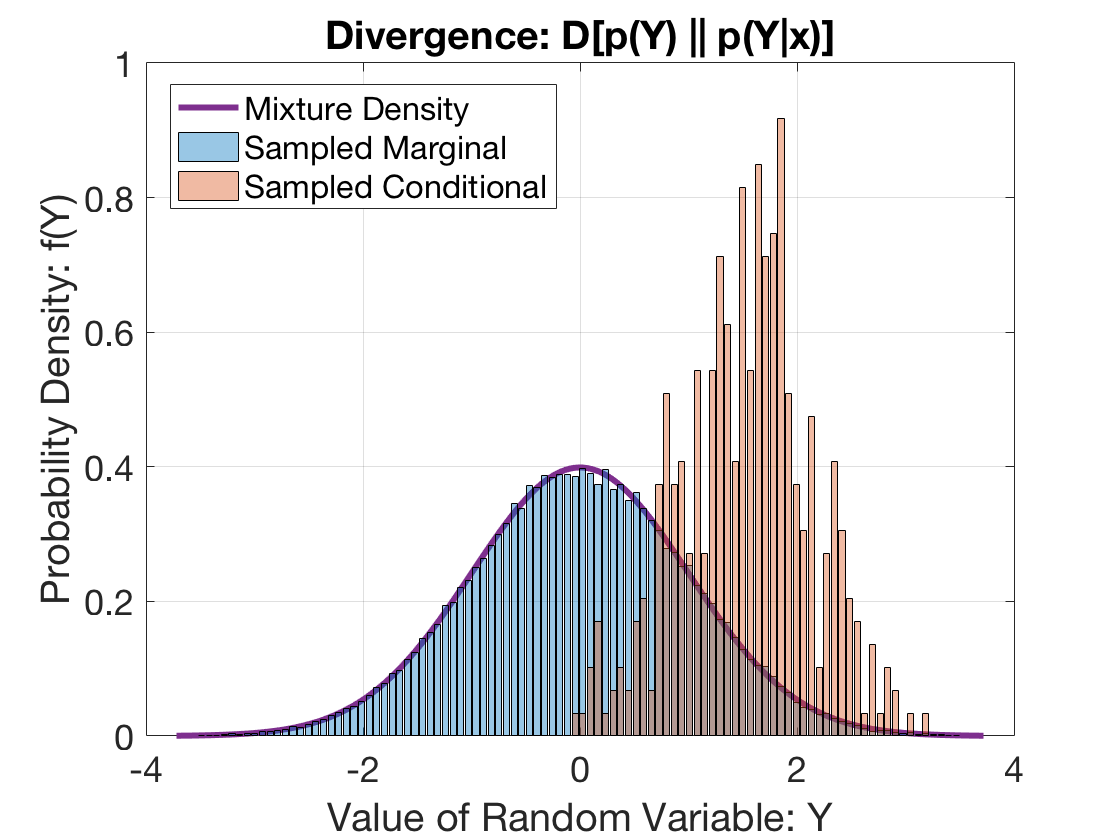


% Plot the marginal and conditional distribution:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
[Xtheoretical,Ytheoretical] = plot_mixture_density(jointDensity.marginal{2});
xfig = plot(Xtheoretical,Ytheoretical,'color',colors(4,:),'linewidth',3); hold on;
mfig = bar(histCenters(:,2),sum(histProbs,1)/binWidth(2),...
    'facecolor',colors(1,:),'facealpha',0.4);
cfig = bar(histCenters(:,2),histProbs(xBin,:)/sum(histProbs(xBin,:))/binWidth(2),...
    'facecolor',colors(2,:),'facealpha',0.4);

% labels & legend
legend([xfig,mfig,cfig],'Mixture Density','Sampled Marginal','Sampled Conditional','location','best');
ylabel('Probability Density: f(Y)','fontsize',18);
xlabel('Value of Random Variable: Y','fontsize',18);
title('Divergence: D[p(Y) || p(Y|x)]','fontsize',24)

% plotting aesthetics
set(gca,'fontsize',18);
grid on;


% Calculate divergece analytically: h = -integral{p(Y=y|x) * ln[p(Y=y)/p(Y=y|x)], dy}
% Only do this if there is a single Gaussian kernel in each marginal:
dTrue = 0/0;
if nKernels == 1 && strcmpi(kernelType,'Normal')

    % pull parameters from the joint distribution
    sgX = jointDensity.marginal{1}.params{1}(2)^2;
    sgY = jointDensity.marginal{2}.params{1}(2)^2;
    muX = jointDensity.marginal{1}.params{1}(1);
    muY = jointDensity.marginal{2}.params{1}(1);
    sgXY = jointDensity.copulaCovariance(1,2) * sqrt(sgX) * sqrt(sgY);
    
    % conditional distribution parameters
    sgYx = sgY - sgXY^2/sgX;
    muYx = muY + sgXY/sgX * (xVal-muX);

    % divergence calculation
    dTrue = 1/2*log(sgY/sgYx) + (sgYx + (muYx-muY)^2)/(2*sgY) - 1/2;
end

% Probabilities of marginal and conditional:
Pxy  = histProbs;
Py   = squeeze(sum(Pxy,1)); Py = Py(:);
Pygx = Pxy(xBin,:);         Pygx = Pygx(:);
Pygx = Pygx/sum(Pygx); 

% Check that all probabilities sum to 1:
assert(abs(sum(Pygx)-1) < 1/nSamples^2)
assert(abs(sum(Py)-1) < 1/nSamples^2)

% Calculate divergence:
dDifferential = -Pygx(Pygx>0)' * log(Py(Pygx>0)./Pygx(Pygx>0));

% Screen report:
fprintf(['Estimates of Divergence with %d bins with %d samples: \n' ...
    '--- Analytic:   D = %f [nats] \n' ...
    '--- Numerical:  D = %f [nats] '], ...
    nBins,nSamples,dTrue,dDifferential);

Estimates of Divergence with 100 bins with 100000 samples: 
--- Analytic:   D = 1.402047 [nats] 
--- Numerical:  D = 1.433236 [nats] 

## Step 5: Mutual Information is Expected Divergence

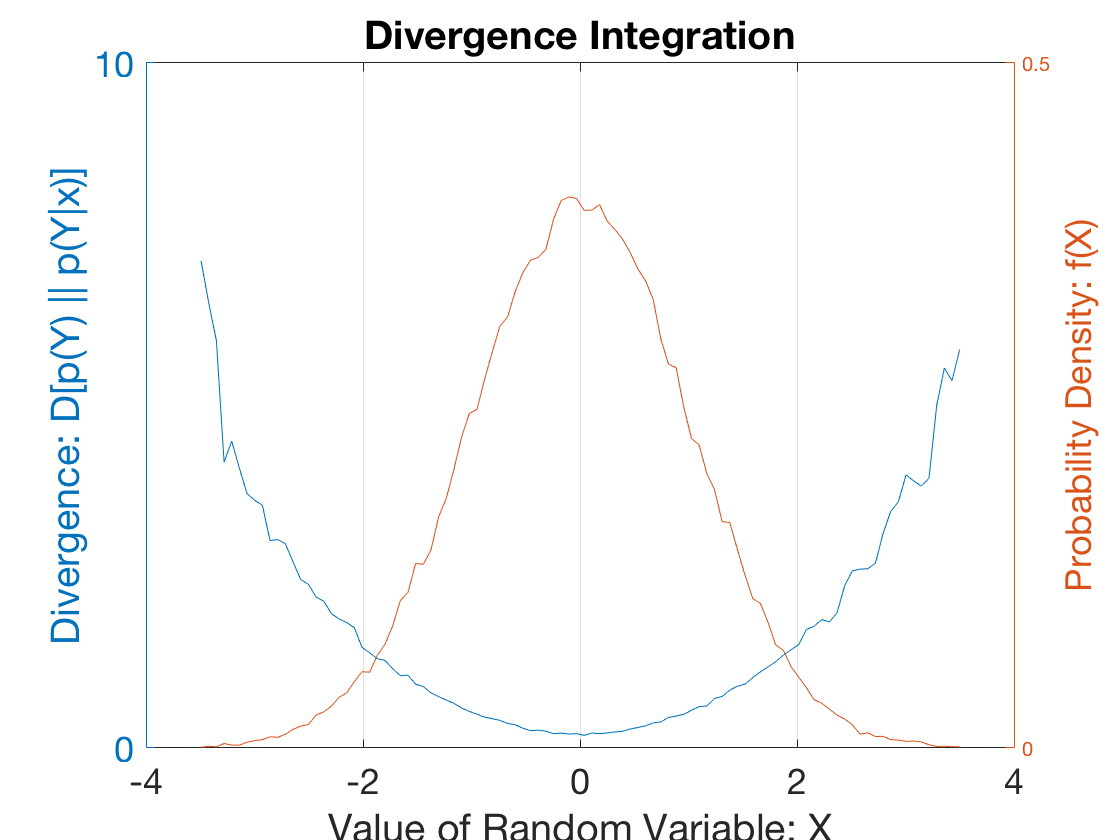

% Calculate divergece analytically: h = -integral{p(Y=y|x) * ln[p(Y=y)/p(Y=y|x)], dy}
% Only do this if there is a single Gaussian kernel in each marginal:
iTrue = 0/0;
if nKernels == 1 && strcmpi(kernelType,'Normal')
    iTrue = -1/2 * log(det(jointDensity.copulaCovariance));
end

% Probabilities of joint and marginals:
Pxy = histProbs;
Px  = squeeze(sum(Pxy,2)); Px = Px(:);
Py  = squeeze(sum(Pxy,1)); Py = Py(:);

% Check that all probabilities sum to 1:
assert(abs(sum(Px)-1) < 1/nSamples^2)
assert(abs(sum(Py)-1) < 1/nSamples^2)
assert(abs(sum(Pxy(:))-1) < 1/nSamples^2)

% Calculate MI explicitly as a summation over divergences:
dInteg = zeros(nBins,1)./0; % init storage
for xBin = 1:nBins
    
    % Conditional probabilities:
    Pygx = Pxy(xBin,:);         
    Pygx = Pygx(:);
    Pygx = Pygx/sum(Pygx); 
    
    % Check that all probabilities sum to 1:
    assert(abs(sum(Pygx)-1) < 1/nSamples^2)
    
    % Calculate mutual information:
    dInteg(xBin) = -Pygx(Pygx>0)' * log(Py(Pygx>0)./Pygx(Pygx>0));
    
end % x-loop

% Plot each divergence from conditional:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
hyy = plotyy(histCenters(:,1),dInteg,histCenters(:,1),Px/sum(Px)/binWidth(1));

% labels & legend
hyy(1).YLabel.String = 'Divergence: D[p(Y) || p(Y|x)]';
hyy(2).YLabel.String = 'Probability Density: f(X)';
hyy(1).YLabel.FontSize = 18;
hyy(2).YLabel.FontSize = 18;
xlabel('Value of Random Variable: X','fontsize',18);
title('Divergence Integration','fontsize',24)

% plotting aesthetics
set(gca,'fontsize',18);
grid on;


% Sum to approximate integral:
iInteg = Px' * dInteg;

% Calculate marginal and joint entropies:
Hx = -Px(Px>0)'*log(Px(Px>0));
Hy = -Py(Py>0)'*log(Py(Py>0));
Hxy = -Pxy(Pxy>0)'*log(Pxy(Pxy>0));

% Calculate mutual information:
iEntropy = Hx+Hy-Hxy;

% Screen report:
fprintf(['Estimates of Mutual Information with %d bins with %d samples: \n' ...
    '--- Analytic Differential:  I(X;Y) = %f [nats] \n' ...
    '--- Integrating Divs:       I(X;Y) = %f [nats] \n' ...
    '--- Entropy Subtraction:    I(X;Y) = %f [nats]'],...
    nBins,nSamples,iTrue,iInteg,iEntropy);

Estimates of Mutual Information with 100 bins with 100000 samples: 
--- Analytic Differential:  I(X;Y) = 0.510826 [nats] 
--- Integrating Divs:       I(X;Y) = 0.536623 [nats] 
--- Entropy Subtraction:    I(X;Y) = 0.536623 [nats]

## Step 6: As a Function of Sample Size and Bin Counts

% Increasing sample size:
nSampleSizes = 10;
sampleSizes = unique(round(logspace(1,6,nSampleSizes)));

% Increasing number of histogram bins:
nBinCounts = 7;
binCounts = unique(round(logspace(1,3,nBinCounts)));

% Number of resampling experiments:
nResamples =1;

% Initialize storage:
iConvergence = zeros(nSampleSizes,nBinCounts,nResamples)./0;

% Loop through resampling experiments:
for r = 1:nResamples
    
    % Initialize progress bar:
    totalCalcs = nSampleSizes * nBinCounts;
    timerCalcs = round(linspace(1,totalCalcs,50));
    calcCount = 0;
    fprintf('Sample #%d of %d ... \n',r,nResamples);
    fprintf(strcat(repmat('.',[1,50]),'\n')); tic;
    
    % Loop through sample sizes and bin counts:
    for s = 1:nSampleSizes
        
        % Draw one master sample from the mixture density:
        resample = sample_joint_density(jointDensity,sampleSizes(s));
        
        for c = 1:nBinCounts
            
            % Screen report:
            calcCount = calcCount + 1;
            if ismember(calcCount,timerCalcs); fprintf('.'); end
            
            % Calculate information:
            iConvergence(s,c,r) = ...
                hist_info(resample(:,1),resample(:,2),binCounts(c));
            
        end % c-loop
    end % s-loop
    
    % Screent report:
    fprintf('time = %f[s] \n\n',toc);
    
end % r-loop

Sample #1 of 1 ... 


..................................................


..................................................

time = 41.869578[s] 



## Step 6.1: Plot Convergence Estimates

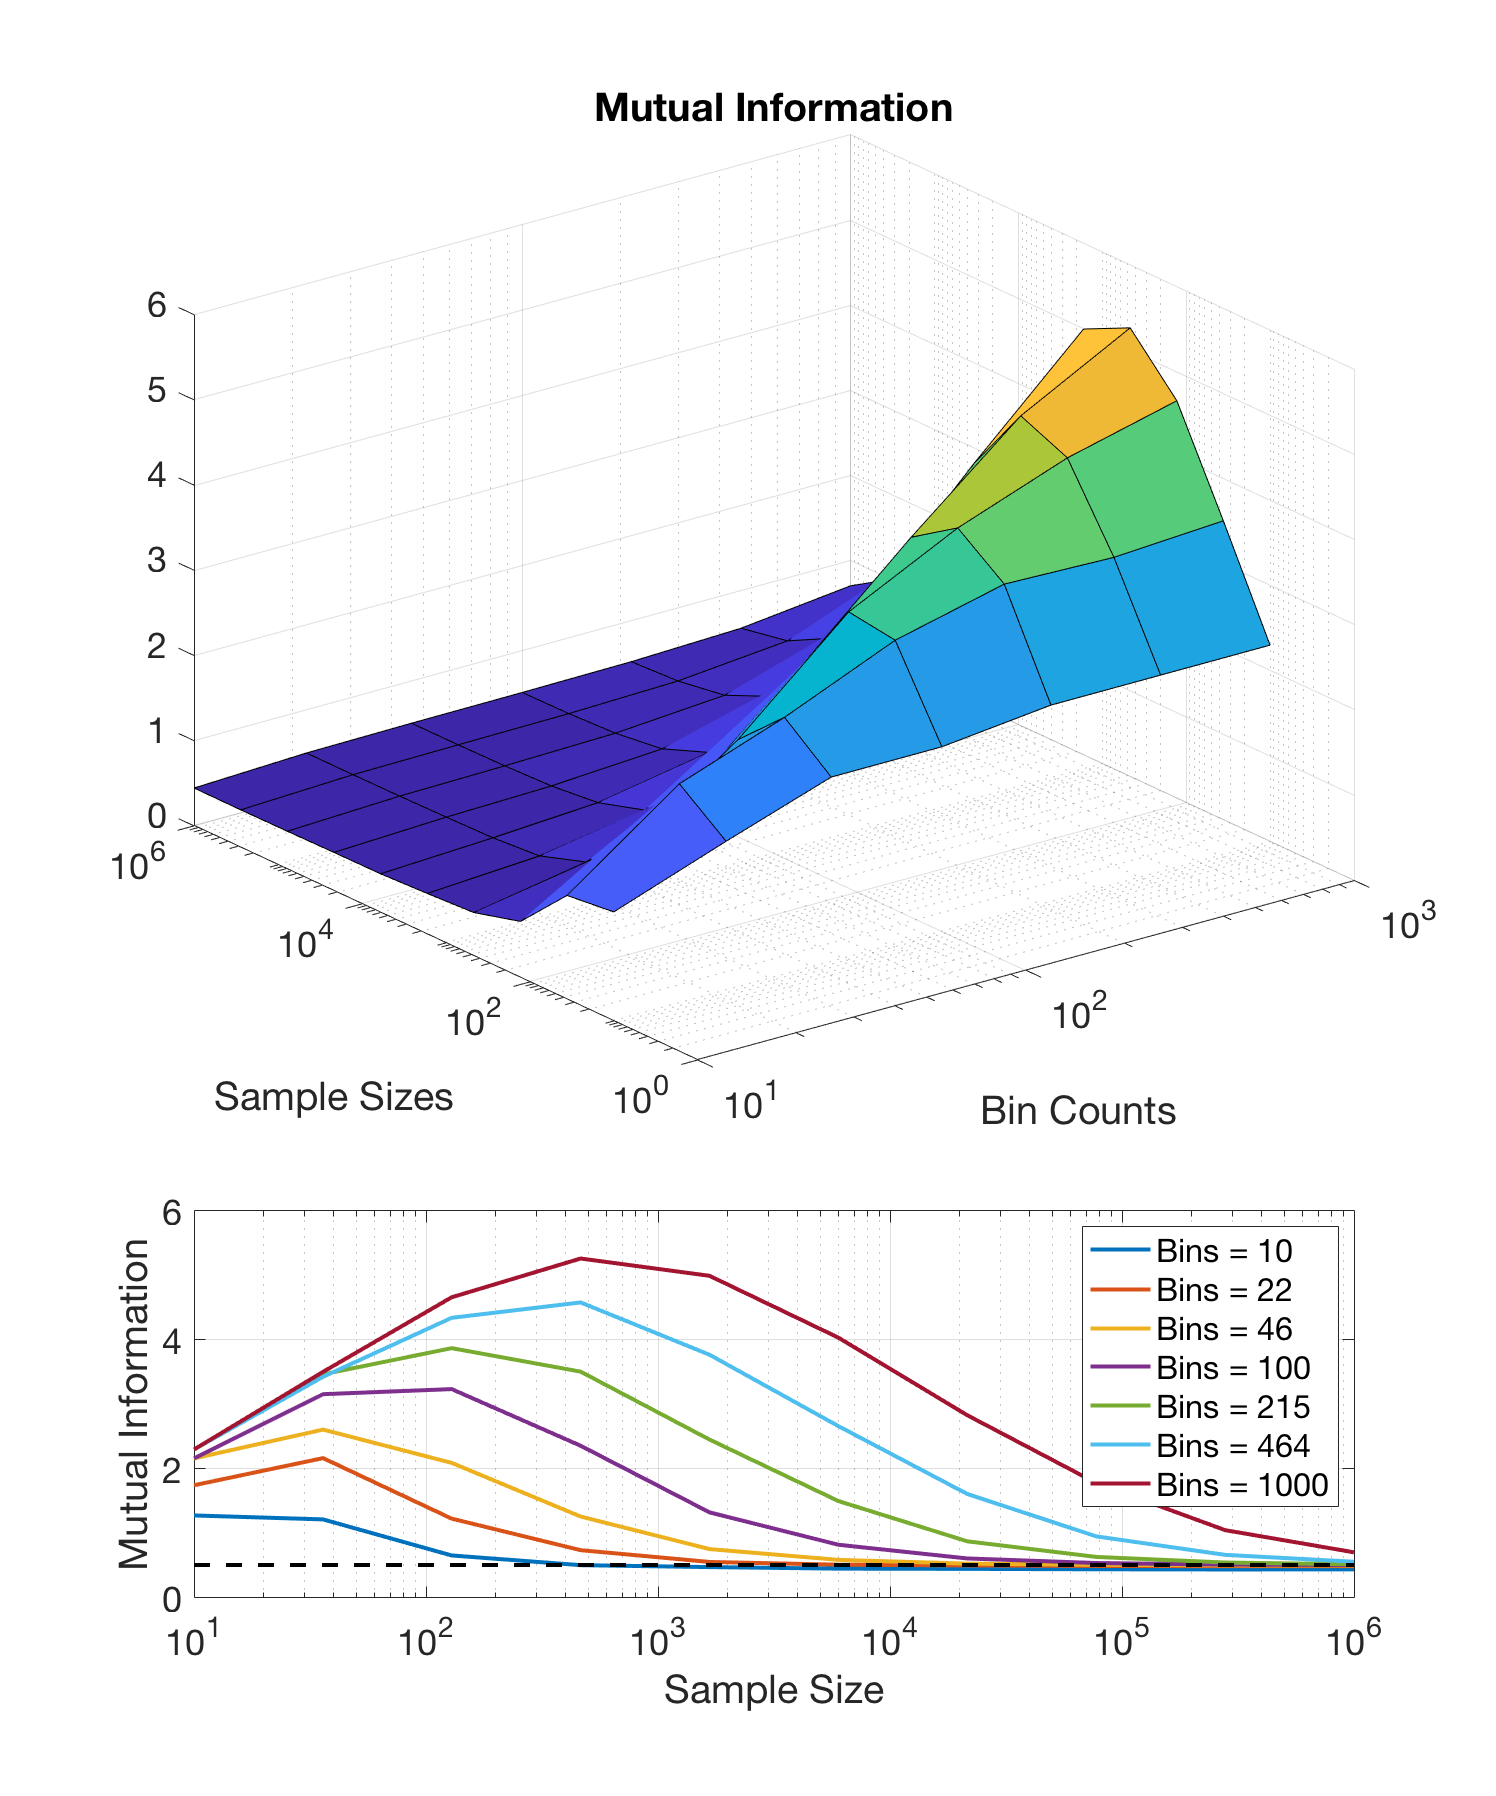

% Initialize a figure for plotting entropy estimates:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
set(gcf,'position',[1,1,1000,1200]); 

% Plot discrete entropies:
subplot(3,1,1:2)
surf(binCounts,sampleSizes,mean(iConvergence,3));

% Aesthetics:
set(gca,'Xscale','log','Yscale','log')
xlabel('Bin Counts')
ylabel('Sample Sizes')
title('Mutual Information')
set(gca,'fontsize',18);
grid on;

% Plot discrete entropies:
subplot(3,1,3)
plot(sampleSizes,mean(iConvergence,3),'linewidth',2); hold on;
plot([sampleSizes(1),sampleSizes(end)],[iTrue,iTrue],'k--','linewidth',2)

% Aesthetics:
legendCell = cellstr(num2str(binCounts','Bins = %-d'));
legend(legendCell)
set(gca,'Xscale','log')
xlabel('Sample Size')
ylabel('Mutual Information')
set(gca,'fontsize',18);
set(gca,'xlim',[sampleSizes(1),sampleSizes(end)])
grid on;